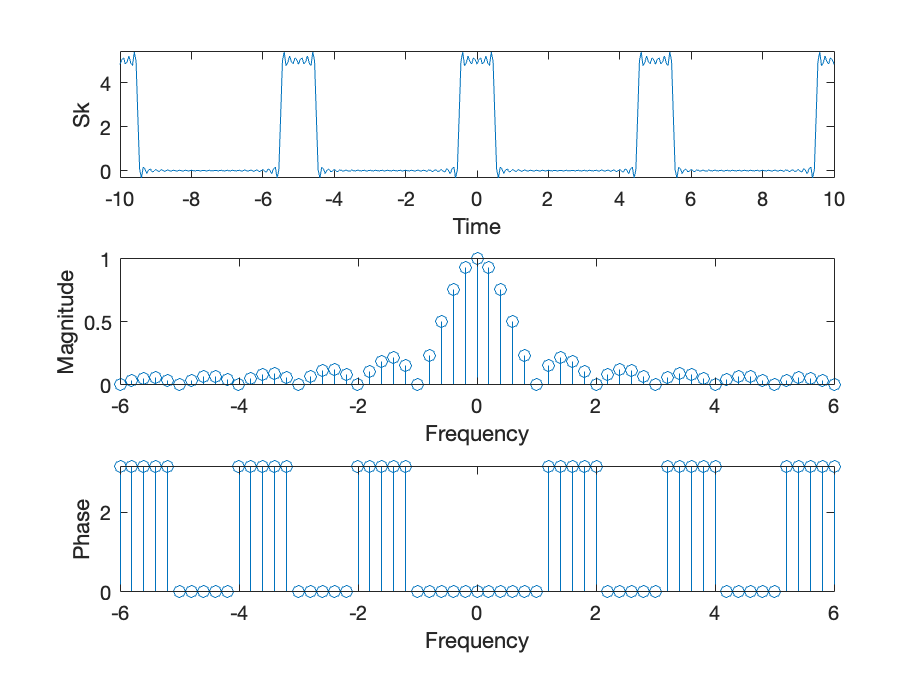



clear;
%declare varibles
N=30;
tau=1; 
T_0=5; 
A=5;
ts=-2*T_0; 
tf=2*T_0; 
t_st=T_0/100;
% t is an array from -2t0 to 2t0 with increments of 5/100
t=ts:t_st:tf;

%loop for 30 iterations 
for z=1:30
ks = -z; kf = z; x = 0;

%loop from -z to z, if k equals 0 then ks is A*tau/T_0. 
% Other than that sk equals 
% ((A*tau)/T_0)* (sin(pi*k*tau/T_0) / (pi*k*tau/T_0))
for k=ks:kf if k == 0
Sk = A*tau/T_0; else
Sk = ((A*tau)/T_0)* (sin(pi*k*tau/T_0) / (pi*k*tau/T_0));
end

% defining all variables after have gone through all loops
f(k+kf+1) = k/T_0; magnitude(k+kf+1) = abs(Sk); phase(k+kf+1) = angle(Sk);
x = x + (Sk * exp(j*2*pi*k*t/T_0));

end

subplot(3, 1, 1), plot(t, real(x));
xlabel("Time")
ylabel("Sk")

subplot(3, 1, 2), stem(f, magnitude);
xlabel("Frequency")
ylabel("Magnitude")

subplot(3, 1, 3), stem(f, phase); pause(.3)
xlabel("Frequency")
ylabel("Phase")

end